%==========================================================================
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan, Ann Arbor
% Contact:   nakhavan@umich.edu
%
%
% Last updated: March 2026
%==========================================================================
clear; clc; close all;


## Long-wake DROP threshold

WAKE_BREAK_MIN = 2;
WAKE_BREAK_SEC = WAKE_BREAK_MIN * 60;   % 120 s

ALLOW_TOTALWAKE_FALLBACK = true;


## Paths

mouseLightCSV = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse light data-Naghmeh\BigResultTable_mouse_light.csv";
mouseDarkCSV  = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Mouse DATA\Mouse dark data-Naghmeh\BigResultTable_mouse_dark.csv";
ratLightCSV   = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat light data-Naghmeh\BigResultTable_rat_light.csv";
ratDarkCSV    = "C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\Rat DATA\Rat dark data-Naghmeh\BigResultTable_rat_dark.csv";


## Knobs

NEAR_FUTURE_SEC = 30;     % Delta t horizon (seconds)
NBINS_HIST      = 60;     % fallback histogram bins when too few samples
CDF_LO          = 0.005;  % increasing-zone search band (lo)
CDF_HI          = 0.98;   % increasing-zone search band (hi)

% FIXED REMpre edges in SECONDS (6 bins -> 7 edges)
REM_EDGES_SEC   = [0 30 60 90 120 150 inf];

% Force axis to 0..XLM_SEC everywhere
% same scale for every panels
XLM_SEC         = 3000;

% Colors
mouseColor = [0.55 0.27 0.68];   % purple
ratColor   = [0.90 0.50 0.10];   % orange

% Jitter (Helps reduce discretization combs)
JITTER_FRAC = 0.25;   % fraction of epoch (<= 1/4)

% Epoch lengths (s) – only used to scale the jitter
EPOCH_MOUSE = 2.5;
EPOCH_RAT   = 4.0;


## Datasets

Mouse (Light): Total=5300 | Kept=4017 | Dropped=1283  [LW by total Wake >= thr (PROXY; not max-block); thr=2 min]


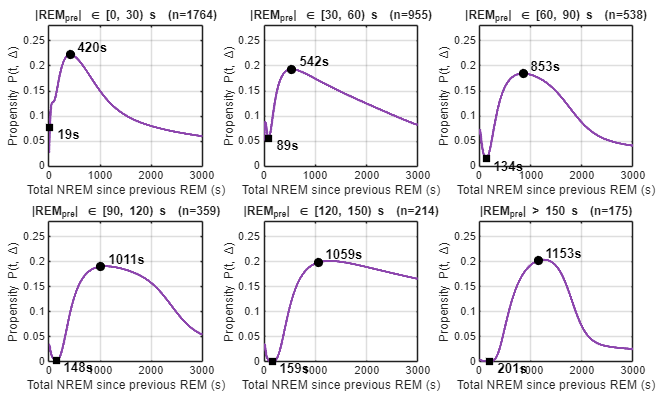


Extrema (seconds) for Mouse (Light):
    Bin_REMpre_s    LastLocalMax_s    GlobalMin_s
    ____________    ______________    ___________

    "[0, 30)"             420              19    
    "[30, 60)"            542              89    
    "[60, 90)"            853             134    
    "[90, 120)"          1011             148    
    "[120, 150)"         1059             159    
    "[150, Inf)"         1153             201    



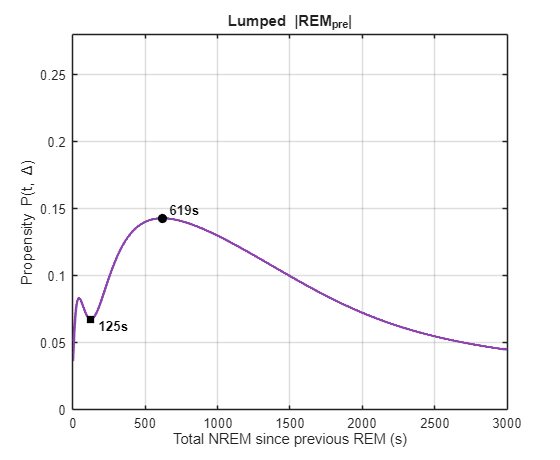

Lumped extrema (seconds):
     Panel      LastLocalMax_s    GlobalMin_s
    ________    ______________    ___________

    "Lumped"         619              125    



run_one(mouseLightCSV, "Mouse", "Light", mouseColor, REM_EDGES_SEC, EPOCH_MOUSE, ...
        NEAR_FUTURE_SEC, NBINS_HIST, CDF_LO, CDF_HI, XLM_SEC, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, ALLOW_TOTALWAKE_FALLBACK);

Mouse (Dark): Total=1307 | Kept=743 | Dropped=564  [LW by total Wake >= thr (PROXY; not max-block); thr=2 min]


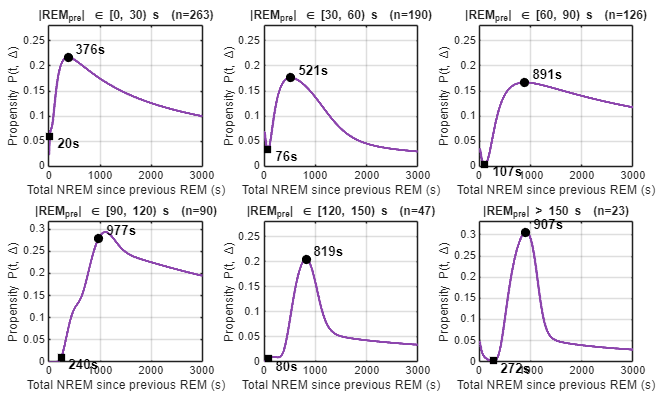


Extrema (seconds) for Mouse (Dark):
    Bin_REMpre_s    LastLocalMax_s    GlobalMin_s
    ____________    ______________    ___________

    "[0, 30)"            376               20    
    "[30, 60)"           521               76    
    "[60, 90)"           891              107    
    "[90, 120)"          977              240    
    "[120, 150)"         819               80    
    "[150, Inf)"         907              272    



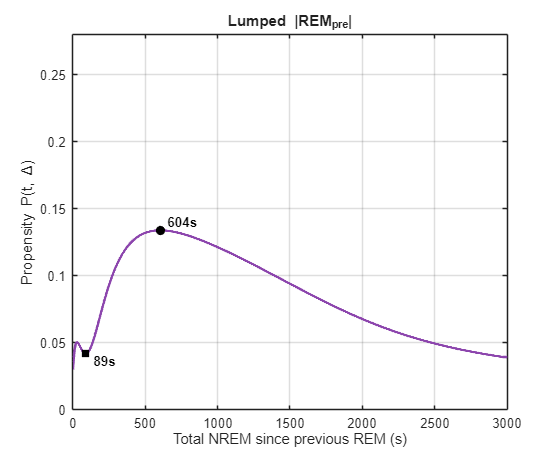

Lumped extrema (seconds):
     Panel      LastLocalMax_s    GlobalMin_s
    ________    ______________    ___________

    "Lumped"         604              89     




run_one(mouseDarkCSV,  "Mouse", "Dark",  mouseColor, REM_EDGES_SEC, EPOCH_MOUSE, ...
        NEAR_FUTURE_SEC, NBINS_HIST, CDF_LO, CDF_HI, XLM_SEC, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, ALLOW_TOTALWAKE_FALLBACK);

Rat (Light): Total=2766 | Kept=2092 | Dropped=674  [LW by total Wake >= thr (PROXY; not max-block); thr=2 min]


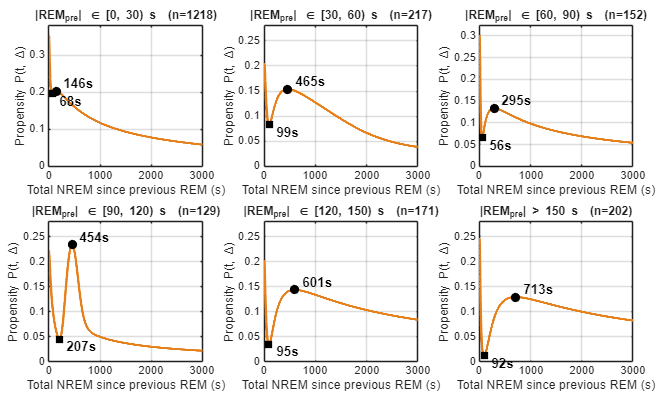


Extrema (seconds) for Rat (Light):
    Bin_REMpre_s    LastLocalMax_s    GlobalMin_s
    ____________    ______________    ___________

    "[0, 30)"            146               68    
    "[30, 60)"           465               99    
    "[60, 90)"           295               56    
    "[90, 120)"          454              207    
    "[120, 150)"         601               95    
    "[150, Inf)"         713               92    



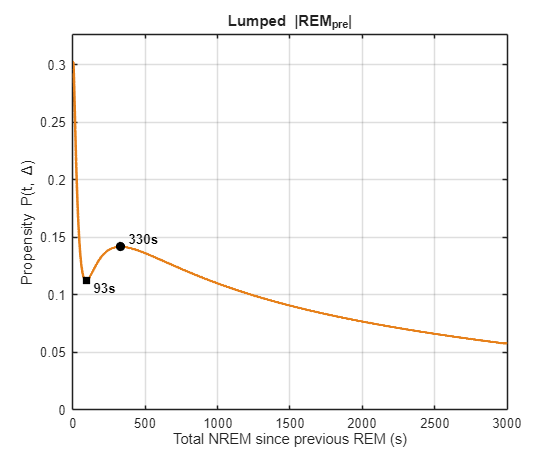

Lumped extrema (seconds):
     Panel      LastLocalMax_s    GlobalMin_s
    ________    ______________    ___________

    "Lumped"         330              93     




run_one(ratLightCSV,   "Rat",   "Light", ratColor,   REM_EDGES_SEC, EPOCH_RAT, ...
        NEAR_FUTURE_SEC, NBINS_HIST, CDF_LO, CDF_HI, XLM_SEC, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, ALLOW_TOTALWAKE_FALLBACK);

Rat (Dark): Total=2312 | Kept=1747 | Dropped=565  [LW by total Wake >= thr (PROXY; not max-block); thr=2 min]


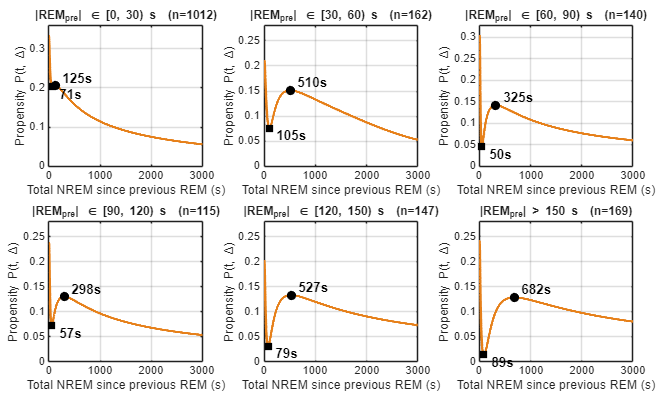


Extrema (seconds) for Rat (Dark):
    Bin_REMpre_s    LastLocalMax_s    GlobalMin_s
    ____________    ______________    ___________

    "[0, 30)"            125               71    
    "[30, 60)"           510              105    
    "[60, 90)"           325               50    
    "[90, 120)"          298               57    
    "[120, 150)"         527               79    
    "[150, Inf)"         682               89    



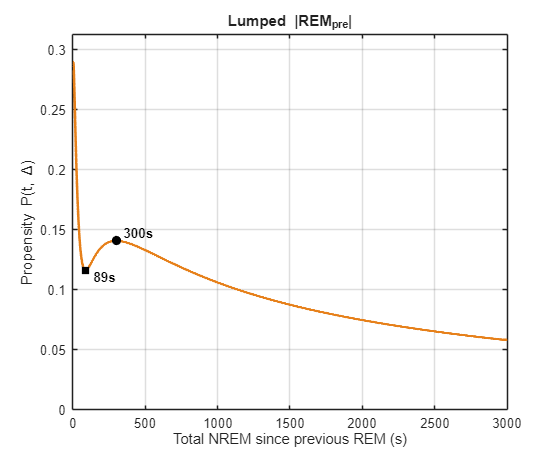

Lumped extrema (seconds):
     Panel      LastLocalMax_s    GlobalMin_s
    ________    ______________    ___________

    "Lumped"         300              89     




run_one(ratDarkCSV,    "Rat",   "Dark",  ratColor,   REM_EDGES_SEC, EPOCH_RAT, ...
        NEAR_FUTURE_SEC, NBINS_HIST, CDF_LO, CDF_HI, XLM_SEC, JITTER_FRAC, ...
        WAKE_BREAK_SEC, WAKE_BREAK_MIN, ALLOW_TOTALWAKE_FALLBACK);


fprintf('Done.\n');

Done.


## Function

% runs once per dataset
function run_one(csvPath, species, phase, curveColor, REM_EDGES_SEC, epochSec, ...
                 NEAR_FUTURE_SEC, NBINS_HIST, CDF_LO, CDF_HI, XLM_SEC, JITTER_FRAC, ...
                 WAKE_BREAK_SEC, WAKE_BREAK_MIN, ALLOW_TOTALWAKE_FALLBACK)

    assert(isfile(csvPath), 'CSV not found: %s', csvPath);
    R = readtable(csvPath, 'TextType','string');

    % Ensure required numeric cols
    needR = ["REMpre","NREM","Wake","Movement","IREM"];
    for v = needR
        if ~ismember(v, string(R.Properties.VariableNames)), R.(v) = NaN(height(R),1); end
        R.(v) = double(R.(v));
    end
    % reconstruct IREM if missing/all NaN
    if (~ismember("IREM", string(R.Properties.VariableNames))) || all(isnan(R.IREM))
        if all(ismember(["NREM","Wake","Movement"], string(R.Properties.VariableNames)))
            R.IREM = R.NREM + R.Wake + R.Movement;
        end
    end

    % Long-wake filtering
    [dropFlag, filterMsg] = longwake_dropflag(R, WAKE_BREAK_SEC, ALLOW_TOTALWAKE_FALLBACK);

    keptTbl = R(~dropFlag, :);
    fprintf('%s (%s): Total=%d | Kept=%d | Dropped=%d  [%s; thr=%g min]\n', ...
            species, phase, height(R), height(keptTbl), sum(dropFlag), filterMsg, WAKE_BREAK_MIN);

    % Arrays (seconds)
    N_s   = keptTbl.NREM;     % |N| = NREM seconds
    RP_s  = keptTbl.REMpre;   % REMpre seconds for *fixed-edge* binning

    % keep only valid cycles
    valid = isfinite(N_s) & (N_s > 0) & isfinite(RP_s) & (RP_s >= 0);
    N_s   = N_s(valid);
    RP_s  = RP_s(valid);

    if numel(N_s) < 30
        warning('%s (%s): Not enough valid cycles for propensity (n=%d).', species, phase, numel(N_s));
        return;
    end

    % Small jitter to mitigate discretization combs
    if JITTER_FRAC > 0
        jitter = (rand(numel(N_s),1)-0.5) * (2*JITTER_FRAC*epochSec);
        N_s    = max(N_s + jitter, eps);
    end

    % Bin assignment - Fixed REMpre binning (1-6)
    binID = discretize(RP_s, REM_EDGES_SEC);
    nBins = numel(REM_EDGES_SEC)-1;


## Define GMM and CDF functions


    % Define a 2-comp GMM fitter on log-seconds
    fit2 = @(z) fit_gmm_1d(z, 2, struct( ...
        'nStarts',30,'maxIter',250,'tol',1e-6, ...
        'trimFrac',0.0,'sdMin',0.04,'sdMax',4.0, ...
        'clipQuantiles',[0 100]));  % no clipping

    % Define standard normal CDF and mixture CDF in seconds
    Phi = @(u) 0.5*(1+erf(u./sqrt(2)));
    gmm_cdf_seconds = @(t, w, mu, sd) arrayfun(@(tt) sum(w .* Phi((log(max(tt,eps))-mu)./sd)), t(:)).';



## Figure 1: 2*3 fixed-bin propensity

    % Choose tiled layout and create the figure
    [r,c] = layout_for_bins(nBins);     % 6 -> 2x3
    fBins = figure('Color','w','Position',[80 50 1180 700], ...
                   'Name', sprintf('%s (%s): Propensity (fixed REM_{pre} bins)', species, phase));
    tlBins = tiledlayout(r,c,'TileSpacing','compact','Padding','compact');
    % Initialize arrays to store extrema times
    lastLocalMax_bins = NaN(nBins,1);
    globalMin_bins    = NaN(nBins,1);
    % Loop over bins and draw each panel
    for b = 1:nBins
        ax = nexttile(tlBins); hold(ax,'on');
        inBin = (binID == b);
        Nb_s  = N_s(inBin);

        lo = REM_EDGES_SEC(b); hi = REM_EDGES_SEC(b+1);
        if isinf(hi)
            titleStr = sprintf('|REM_{pre}| > %d s  (n=%d)', lo, sum(inBin));
        else
            titleStr = sprintf('|REM_{pre}| \\in [%d, %d) s  (n=%d)', lo, hi, sum(inBin));
        end

        [lastLocalMax_bins(b), globalMin_bins(b)] = ...
            plot_propensity_panel(ax, Nb_s, titleStr, NEAR_FUTURE_SEC, ...
                CDF_LO, CDF_HI, NBINS_HIST, fit2, gmm_cdf_seconds, curveColor, XLM_SEC);
    end

    % ---- Print extrema summary ----
    fprintf('\nExtrema (seconds) for %s (%s):\n', species, phase);
    binNames = cell(nBins,1);
    for b = 1:nBins
        lo = REM_EDGES_SEC(b); hi = REM_EDGES_SEC(b+1);
        if isinf(hi)
            binNames{b} = sprintf('[%d, Inf)', lo);
        else
            binNames{b} = sprintf('[%d, %d)', lo, hi);
        end
    end

## Print per-bin extrema table

% Build readable bin labels and print
    T_bins = table(string(binNames(:)), lastLocalMax_bins, globalMin_bins, ...
                   'VariableNames', {'Bin_REMpre_s','LastLocalMax_s','GlobalMin_s'});
    disp(T_bins);


## Figure 2: Lumped propensity

% Create lumped figure and plot
    fLump = figure('Color','w','Position',[120 120 560 460], ...
                   'Name', sprintf('%s (%s): Propensity (lumped)', species, phase));
    axL = axes(fLump);
    [lastLocalMax_lumped, globalMin_lumped] = ...
        plot_propensity_panel(axL, N_s, 'Lumped |REM_{pre}|', NEAR_FUTURE_SEC, ...
            CDF_LO, CDF_HI, NBINS_HIST, fit2, gmm_cdf_seconds, curveColor, XLM_SEC);
% Print lumped extrema
    T_lump = table(string("Lumped"), lastLocalMax_lumped, globalMin_lumped, ...
        'VariableNames', {'Panel','LastLocalMax_s','GlobalMin_s'});
    fprintf('Lumped extrema (seconds):\n'); disp(T_lump);
end


## Functions

% longwake_dropflag: Prefer MaxWake* columns (contiguous wake blocks)
function [dropFlag, msg] = longwake_dropflag(T, WAKE_BREAK_SEC, ALLOW_TOTALWAKE_FALLBACK)
    vn = string(T.Properties.VariableNames);

    maxWakeCandidates = ["MaxWakeSec","MaxWake_s", ...
                         "MaxWakeInIREMSec","MaxWakeInIREM_s", ...
                         "MaxWakeBlockSec","MaxWakeBlock_s"];

    idxCol = find(ismember(maxWakeCandidates, vn), 1, 'first');
    if ~isempty(idxCol)
        cname    = maxWakeCandidates(idxCol);
        maxWake  = double(T.(cname));
        dropFlag = isfinite(maxWake) & (maxWake >= WAKE_BREAK_SEC);
        msg      = sprintf("LW by max Wake block (%s)", cname);
        return;
    end

    if ALLOW_TOTALWAKE_FALLBACK && ismember("Wake", vn)
        w = double(T.Wake);
        dropFlag = isfinite(w) & (w >= WAKE_BREAK_SEC);
        msg = "LW by total Wake >= thr (PROXY; not max-block)";
        warning('Using TOTAL Wake as LW proxy (no MaxWake* column). This is not equivalent to max-block filtering.');
        return;
    end

    dropFlag = false(height(T),1);
    msg = "NO LW info (no MaxWake*; total-Wake fallback disabled) => no LW filtering";
    warning('No MaxWake* column and fallback disabled: no long-wake filtering applied.');
end


## Functions

% plot_propensity_panel: If too few cycles, histogram fallback
% fit GMM on z
% compute propensity on a fixed time axis
% define search window using CDF band
% smooth propensity for robust extrema
% find valley then peak
% plot and annotation
function [tLastMax, tGlobMin] = plot_propensity_panel(ax, Nbin_s, titleStr, ...
        NEAR_FUTURE_SEC, CDF_LO, CDF_HI, NBINS_HIST, fit2, gmm_cdf_seconds, curveColor, XLM_SEC)

    axes(ax); cla(ax);

    z = log(Nbin_s(:)); z = z(isfinite(z));
    if numel(z) < 20
        histogram(Nbin_s, min(NBINS_HIST, max(10, round(numel(Nbin_s)/3))), ...
            'Normalization','pdf','FaceAlpha',0.15,'EdgeColor',[0.6 0.6 0.6]);
        title(sprintf('%s\n[n=%d, too few for GMM]', titleStr, numel(Nbin_s)));
        grid on; box on; xlim([0 XLM_SEC]); tLastMax=NaN; tGlobMin=NaN; return;
    end

    [w, mu, sd] = fit2(z);

    % Evaluate up to XLM_SEC; propensity defined only up to (XLM_SEC-Δ)
    t = 1:(XLM_SEC - NEAR_FUTURE_SEC);
    F    = gmm_cdf_seconds(t, w, mu, sd);
    Ftau = gmm_cdf_seconds(t + NEAR_FUTURE_SEC, w, mu, sd);
    P    = (Ftau - F) ./ max(1 - F, eps);     % propensity

    % Search window for extrema
    searchMask = (F >= CDF_LO) & (F <= CDF_HI);

    % Gentle smoothing
    win = max(7, min(21, 1 + 2*round(0.015 * nnz(searchMask))));
    Ps  = P;
    if numel(Ps) >= win, Ps = movmean(Ps, win, 'omitnan'); end

    % Adaptive separation
    idx = find(searchMask);
    if isempty(idx)
        tLastMax=NaN; tGlobMin=NaN;
    else
        winLen       = idx(end) - idx(1) + 1;
        MIN_SEP_SEC  = max(15, round(0.05 * winLen));
        MIN_PROM     = 0.002;
        [imin, imax] = first_valley_then_peak(Ps, searchMask, MIN_SEP_SEC, MIN_PROM);
        tGlobMin = imin;   tLastMax = imax;
    end

    % Extend curve flat to XLM_SEC for nicer panel filling
    t_plot = [t, XLM_SEC];
    P_last = P(end);
    P_plot = [P, P_last];

    plot(t_plot, P_plot, '-', 'LineWidth', 1.9, 'Color', curveColor); hold on;
    ylabel('Propensity P(t, \Delta)'); xlabel('Total NREM since previous REM (s)');
    title(titleStr);
    grid on; box on; xlim([0 XLM_SEC]);

    Pf = P(isfinite(P)); pMax = 0; if ~isempty(Pf), pMax = max(Pf); end
    ylim([0, max(0.28, min(0.5, 1.08*pMax))]);

    % Markers
    if exist('tGlobMin','var') && ~isnan(tGlobMin)
        scatter(t(tGlobMin), P(tGlobMin), 48, 'k', 'filled', 's');
        text(t(tGlobMin), P(tGlobMin), sprintf('  %ds', t(tGlobMin)), ...
             'Color','k','FontWeight','bold','VerticalAlignment','top');
    end
    if exist('tLastMax','var') && ~isnan(tLastMax)
        scatter(t(tLastMax), P(tLastMax), 48, 'k', 'filled');
        text(t(tLastMax), P(tLastMax), sprintf('  %ds', t(tLastMax)), ...
             'Color','k','FontWeight','bold','VerticalAlignment','bottom');
    end
end

function [imin, imax] = first_valley_then_peak(Ps, searchMask, minSepSec, minProm)
    Ps = Ps(:)'; N = numel(Ps);
    idx = find(searchMask);
    if isempty(idx), imin=NaN; imax=NaN; return; end
    lo = idx(1); hi = idx(end);

    % valley (first local min; else global min in window)
    mins = islocalmin(Ps, 'MinProminence', minProm);
    candMin = find(mins & (1:N)>=lo & (1:N)<=hi, 1, 'first');
    if isempty(candMin)
        [~,ii] = min(Ps(lo:hi)); imin = lo + ii - 1;
    else
        imin = candMin;
    end

    % peak (first local max AFTER valley; else global max in window)
    start = min(hi, imin + max(1, round(minSepSec)));
    maxs = islocalmax(Ps, 'MinProminence', minProm);
    candMax = find(maxs & (1:N)>=start & (1:N)<=hi, 1, 'first');

    if isempty(candMax)
        [~,jj] = max(Ps(start:hi));
        imax = start + jj - 1;
    else
        imax = candMax;
    end

    if ~(imax > imin)
        [~,jj] = max(Ps(lo:hi));
        imax = lo + jj - 1;
        if imax <= imin && imax < hi, imax = imin + 1; end
    end
end


## Function

% Standard toolbox-free EM
function [w, mu, sd, info] = fit_gmm_1d(x, K, opts)
% EM for 1-D K-Gaussian mixture with safe option getter.
    x = x(:); x = x(isfinite(x));
    if nargin < 3, opts = struct; end

    function val = gget(field, default)
        if isstruct(opts) && isfield(opts, field) && ~isempty(opts.(field))
            val = opts.(field);
        else
            val = default;
        end
    end

    nStarts  = gget('nStarts',      20);
    maxIter  = gget('maxIter',     300);
    tol      = gget('tol',        1e-6);
    trimFrac = gget('trimFrac',    0.0);
    sdMin    = gget('sdMin',      0.04);
    sdMax    = gget('sdMax',       4.0);
    cq       = gget('clipQuantiles',[0 100]);
    iq       = gget('initQuantiles',[0.30 0.70]);

    % NOTE: uses quantile() (built-in). cq=[0 100] => no clipping.
    qlo = quantile(x, cq(1)/100); qhi = quantile(x, cq(2)/100);
    x   = x(x>=qlo & x<=qhi);

    log2pi = log(2*pi);
    bestLL = -inf; best = [];

    mu_seed = quantile(x, iq);
    for s = 1:nStarts
        if s==1, mu0 = mu_seed; else, mu0 = mu_seed + 0.10*randn(1,K); end
        sd0 = max(sdMin, 0.3*std(x))*ones(1,K);
        w0  = ones(1,K)/K;
        [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
        if LL(end) > bestLL, bestLL = LL(end); best = {w1,mu1,sd1,LL}; end
    end
    [w, mu, sd, LL] = best{:};
    info = struct('loglik',LL,'nStarts',nStarts,'n',numel(x));
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
    n = numel(x); K = numel(w); LL = zeros(maxIter,1); trimN = floor(trimFrac*n);
    for it=1:maxIter
        logp = zeros(n,K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); P = exp(logp - m); s = sum(P,2); gamma = P ./ max(s,eps);

        if trimN>0
            [~,idx]=sort(s,'ascend'); keep=true(n,1); keep(idx(1:trimN))=false;
        else
            keep=true(n,1);
        end

        Nk = sum(gamma(keep,:),1);
        w  = Nk ./ max(sum(Nk),eps); w = max(w,1e-4); w = w/sum(w);
        for k=1:K
            mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k),eps);
            v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k),eps);
            sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
        end

        xk = x(keep);
        logp = zeros(sum(keep),K);
        for k=1:K
            v = sd(k)^2;
            logp(:,k) = -0.5*log2pi - 0.5*log(v) - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
        end
        m = max(logp,[],2); LL(it) = sum(m + log(sum(exp(logp - m),2)));
        if it>1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1))), LL = LL(1:it); break; end
    end
    LL = LL(1:it);
end

%% ---------------- Small layout helper ----------------
function [r,c] = layout_for_bins(n)
    switch n
        case 1,  r=1; c=1;
        case 2,  r=1; c=2;
        case 3,  r=2; c=2;
        case 4,  r=2; c=2;
        case 5,  r=2; c=3;
        case 6,  r=2; c=3;
        otherwise, c = ceil(sqrt(n)); r = ceil(n/c);
    end
end

